Length: **L**

Distributed load: **w**

Elastic Modulus: **E**

Area moment of inertia: **I**

syms w L x
FA = w*L % N

$$FA = L\,w$$

MA = L^2*w/2 % N*m

$$MA = \frac{L^{2}\,w}{2}$$


s(x) = FA - w*x

$$s(x) = L\,w-w\,x$$

M(x) = int(s(x)) - MA

$$M(x) = \frac{w\,x\,\left(2\,L-x\right)}{2}-\frac{L^{2}\,w}{2}$$


% Solve
syms v(x) EI
deq = diff(v,x,2) == M(x)/(EI)

$$deq(x) = \frac{\partial^{2}}{\partial x^{2}}v\left(x\right)=-\frac{\frac{L^{2}\,w}{2}-\frac{w\,x\,\left(2\,L-x\right)}{2}}{\mathrm{EI}}$$

dv = diff(v,x);
bc = [v(0) == 0, dv(0) == 0]

$$bc = \left(\begin{array}{cc} v\left(0\right)=0 & \left({\left(\frac{\partial }{\partial x}v\left(x\right)\right)|}_{x=0}\right)=0 \end{array}\right)$$

vsol = dsolve(deq,bc)

$$vsol = -\frac{6\,w\,L^{2}\,x^{2}-4\,w\,L\,x^{3}+w\,x^{4}}{24\,\mathrm{EI}}$$

simplify(vsol)

$$ans = -\frac{w\,x^{2}\,\left(6\,L^{2}-4\,L\,x+x^{2}\right)}{24\,\mathrm{EI}}$$

**Verified compared to this page:**

[https://mechanicalc.com/reference/beam-deflection-tables](https://mechanicalc.com/reference/beam-deflection-tables)

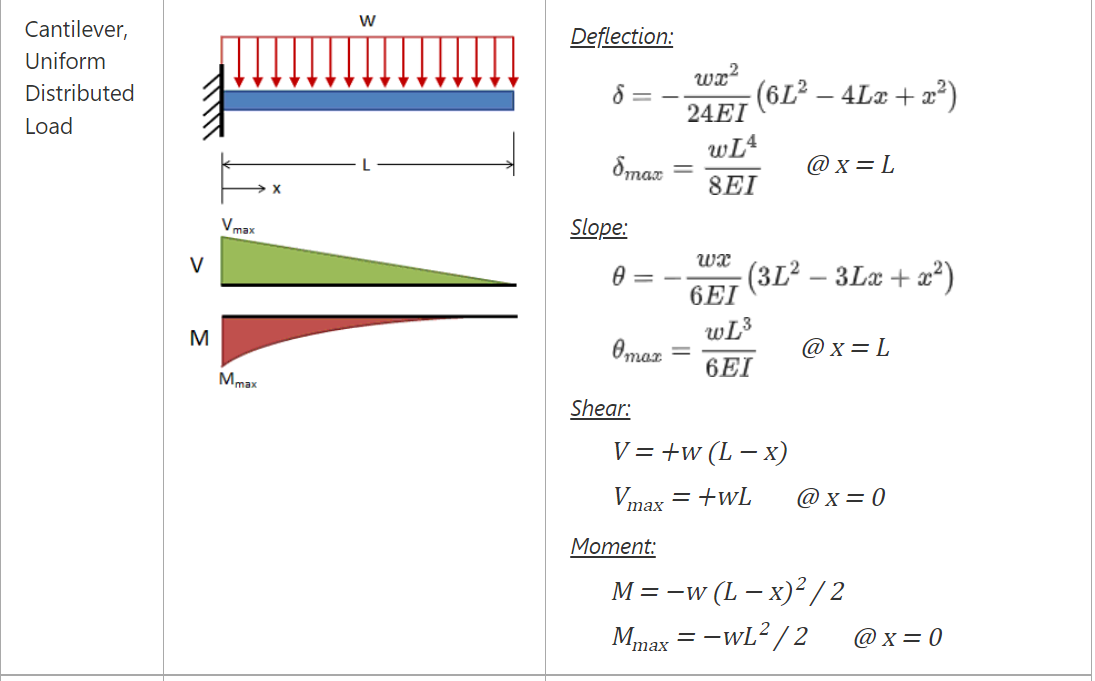

Check for specific values

E = 200 GPa

w = 100 kN/m

L = 6 m

**Solution from script:**


$$$-\frac{x^4 }{43200}+\frac{x^3 }{1800}-\frac{x^2 }{200}$$$


**Check with units:**

u = symunit

u =   symbolicUnitsCollection with units:

      ampere: [A]
      kelvin: [K]
    kilogram: [kg]
       meter: [m]
        mole: [mol]
      second: [s]
     candela: [cd]

  Show all units.



L = 6 * u.m

$$L = 6\,m$$

w = 100 * u.kN/u.m 

$$w = 100\,\frac{\mathrm{kN}}{m}$$

E = 200 * u.GPa

$$E = 200\,\mathrm{GPa}$$

I = sym(0.4*0.3^3/12) * u.m^4

$$I = \frac{9}{10000}\,m^{4}$$

sym x

$$ans = x$$

v(x) = -w*x^2/(24*E*I) *(6*L^2 - 4*L*x + x^2)

$$v(x) = -\frac{625\,x^{2}\,\left(x^{2}-24\,x\,m+216\,m^{2}\right)}{27}\,\frac{\mathrm{kN}}{\mathrm{GPa}\,m^{5}}$$

expand(simplify(v(x)))

$$ans = -\frac{x^{4}}{43200}\,\frac{1}{m^{3}}+\frac{x^{3}}{1800}\,\frac{1}{m^{2}}-\frac{x^{2}}{200}\,\frac{1}{m}$$